% Problem 4

% Part(1)
Ro = 1.15;
K = 10^6;
n = 1:100;

logistic = (K./(1+(K*(Ro-1) - Ro)*Ro.^(-n-1))) - (1/(Ro-1));
Integrator3 = filter(1,[1 -1],logistic);
Total_infections2 = Integrator3(end) % Total infections in 100 days

Total_infections2 = 1.6928e+07

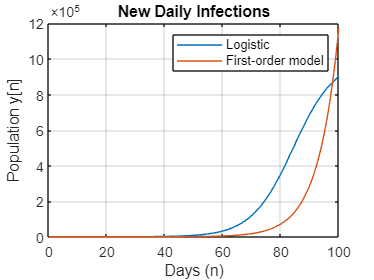


days = 0:100;
Ro = 1.15;
populationx = [0];
for i = days
    populationx(days == i) = Ro^i;
end
figure;
plot(n,logistic)
hold on 
plot(days,populationx)
hold off
title("New Daily Infections")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on
legend("Logistic","First-order model")



% Part(2)
filter_1 = filter([1 -1],1,logistic); % First derivative
filter_2 = filter([1 -2 1],1,logistic); % Second derivative 

Global_maximum = max(filter_1) % Global max value

Global_maximum = 3.4918e+04

Value_n = n(filter_1 == max(filter_1)) % Days corresponding to max value

Value_n = 85

Zero_crossing = n(round(filter_2) == 94) % Inflection point

Zero_crossing = 85

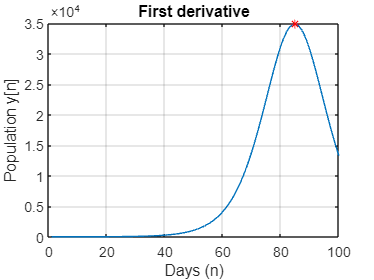


figure;
plot(n,filter_1,n(Value_n),filter_1(Value_n),'r*')
title("First derivative")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on

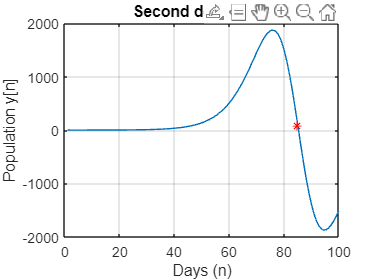


figure;
plot(n,filter_2,n(Zero_crossing),filter_2(Zero_crossing),'r*')
title("Second derivative ")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on